该脚本实现了基于切比雪夫插值的FMM加速计算, 脚本的目标是输入一组二维点集坐标, 核函数A(x,y), 一个特征值迭代中间向量a, 输出一个向量u=Aa

References:The black-box fast multipole method;An Accelerated Kernel-Independent Fast Multipole Method in One Dimension

# **第一节:预计算**

% ==================== 定义参数 =================================
% 其他脚本输入:二维点集unique_coords, 点集的索引unicoord_indics
method=1; % 四叉树划分方式
max_points=100; % 盒子最多点数
min_points=80; % 盒子最少点数
eta = 1; % 分离系数,数字越大不可接受区域越广
use_parallel = 1; % 是否启用并行计算
cheb_num = 6;  % 设置一维方向节点数量
concentration_threshold = [] ; % 点集集中判断标准，设置为[]表示不检查

% % 核函数
mu = 148 ; % 均值
cov = 4e-2 ; % 变异系数
sigma = mu*cov; % 标准差
lx = 0.1; % 相关长度, 注意必须大于节点间距
ly = 0.1;
A = @(x, y) sigma.^2 .* exp( -abs(x(1)-y(1))./lx - abs(x(2)-y(2))./ly );
A_x = @(x1,x2,y1,y2) sigma.^2 .* exp( -abs(x1-y1)./lx - abs(x2-y2)./ly ); % 指数型协方差(向量化)
% % 权重向量
W_sem = diag(R_3.*R_4);

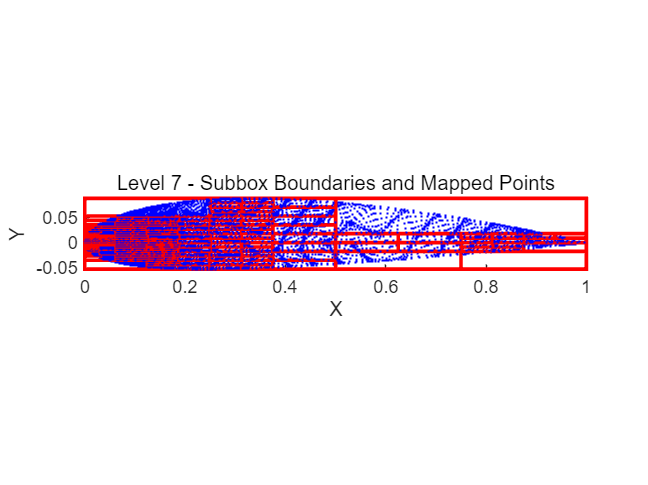

% 构造映射函数句柄 S(a,b)
% S = construct_Sab_chebfun_2D(cheb_num); % a 是标准区间上的切比雪夫插值点，b 是标准区间上的函数值点

S_x = construct_Sab_chebfun_x_2D(cheb_num); % 向量化转移函数

% 构建四叉树
tree_1 = quadtree_2D_decomposition0422(unique_coords, unicoord_indics, ...
    max_points, min_points, method);

% % 构建自适应四叉树
% tree_1 = quadtree_2D_decomposition(unique_coords, unicoord_indics, ...
%     max_points, min_points, method,concentration_threshold);


% 可接受性判断与树结构重构
tree_2 = analyze_level_admissibility_2D(tree_1, eta, use_parallel);

% 使用 chebpts 生成一维切比雪夫节点（第一类切比雪夫点，不包含端点）
cheb_p = chebpts(cheb_num, 1);

% 张量积生成二维网格节点
[X_c, Y_c] = meshgrid(cheb_p, cheb_p);

% 将节点转换为列向量形式，y 优先排序
cheb_nodes = sortrows([X_c(:), Y_c(:)], [2, 1]);

% 将标准区间切比雪夫节点映射到物理单元的每一层的每个盒子上
tree_3 = map_to_box_elements_2D(cheb_nodes, tree_2, use_parallel);

% 将物理单元的每个盒子中的核函数点集映射到上一层的标准区间上
tree_4 = map_points_2D(tree_3, use_parallel);

% % 向量化计算
tree_5 = compute_M2M_L2L_A_x_2D(S_x, cheb_nodes, A_x, tree_4, length(unique_coords), unique_coords, use_parallel);
% 
% % tree_5 = compute_M2M_L2L_A_2D(S, cheb_nodes, A, tree_4, length(unique_coords), unique_coords, use_parallel);

% 返回最终树结构
tree = tree_5;

p_end = 1; % 初始化顶层索引
num_layers = length(tree);
for i = 1:num_layers
    if nnz(tree(i).A_layer) > 0 % 检查A_layer是否非0（使用nnz判断非零元素个数）
        p_end = i; % 顶层
        break;
    end
end
% % 可视化点集划分
visualize_points_2D(tree, num_layers);

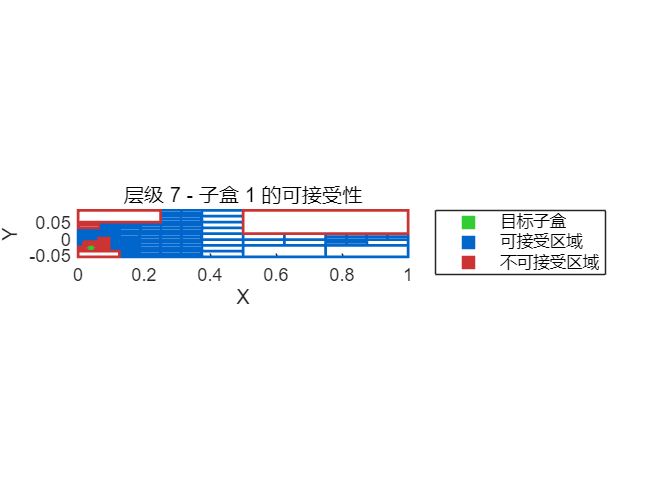

% % 可视化映射点集
% visualize_level_2D(tree, num_layers);
% 可视化可接受性
visualize_admissibility_2D(tree, num_layers, 1,'show_numbers', false);

% 构建树结构
% tree = compute_fmm_tree_2D (unique_coords, unicoord_indics, method, max_points, ...
%     min_points, eta, cheb_num, A,concentration_threshold, use_parallel);


% 预构建近场计算矩阵簇
[A_matrices_grouped, h_unaccept_grouped, indices_grouped] = precompute_near_field_matrices_2D0317(tree);
% 预构建远场嵌套矩阵表达式
f_handle_far = construct_near_expression_2D(p_end,num_layers);
% 最终的FMM句柄函数(乘以迭代向量需要先乘以权函数)
fmm_handle = @(q_1) (f_handle_far(W_sem*q_1, tree) + compute_near_field_contribution_2D0319(A_matrices_grouped, h_unaccept_grouped, indices_grouped,W_sem*q_1,use_parallel));


% p_end = 1; % 初始化顶层索引
% num_layers = length(tree);
% for i = 1:num_layers
%     if nnz(tree(i).A_layer) > 0 % 检查A_layer是否非0（使用nnz判断非零元素个数）
%         p_end = i; % 顶层
%         break;
%     end
% end
% 
% % % 可视化点集划分
% visualize_points_2D(tree, num_layers);
% % 可视化映射点集
% visualize_level_2D(tree, num_layers);
% % 可视化可接受性
% visualize_admissibility_2D(tree, num_layers, 1,'show_numbers', false);

# **第二节: FMM加速计算**

% q_1 = rand(length(unicoord_indics),1)*10; % 特征值迭代中间向量
f_final2 = fmm_handle(q_1);
f_far2=f_handle_far(W_sem*q_1, tree);
far_percent = mean(f_far2./f_final2*100)

far_percent =        38.992


% 结果检验
test = K*q_1;

函数或变量 'K' 无法识别。

gg = mean(abs(f_final2-test))
relative_error = norm(test - f_final2) / norm(f_final2)